clear; clc; close all; fclose all;
ENABLE_DELAY_CH = false;
ENABLE_MULTIPATH_CH = false;
IFFT_FFT_LOOPBACK = true; % Skip DUC,DDC in MATLAB
SW_DUC_DDC_LOOP = false; % Read signals from DUC=>DDC Vivado simulation
SW_DUC = false; % Use DUC (CIC) samples from DUC=>DDC Vivado simulation
SW_TX = false; % Use TX samples from DUC=>DDC Vivado simulation
SW_DDC = false; % Use DDC samples from DUC=>DDC Vivado simulation
SW_DDC_NO_MIX = false; % Use samples from Vivado DUC => DDC simulation without IQ Mixer
SIM_DDC_40M = false; % Generate and analyze samples from DDC Vivado simulation at 40Msps instead of 10Msps
SIM_RX_MIX = false; % Use RX IQ Mixer samples from Vivado ADC simulation
SIM_SYNC_SAMPLES = false; % Create and use samples for Synchronizer 
addpath('Decimate/');
addpath('Interp/');

# **Generate Pilot Subcarriers:**

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% % Pilots for M = 2
rng default
pilot_data_m2 = randsrc(4096*16,1,0:2-1);
file = fopen('../Xilinx/SW_Source/ofdm/files/PilotDataM2.txt','wt');
%file = fopen('PilotDataM2.txt','w');
fprintf(file, "%d\n", pilot_data_m2);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Pilots for M = 4
rng default
pilot_data_m4 = randsrc(4096*16,1,0:4-1);
file = fopen('../Xilinx/SW_Source/ofdm/files/PilotDataM4.txt','wt');
fprintf(file, "%d\n", pilot_data_m4);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Pilots for M = 16
rng default
pilot_data_m16 = randsrc(4096*16,1,0:16-1);
file = fopen('../Xilinx/SW_Source/ofdm/files/PilotDataM16.txt','wt');
fprintf(file, "%d\n", pilot_data_m16);
fclose('all');

# **OFDM Parameters:**

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Read OFDM Parameters from Info file from SW program
file = fopen('../Xilinx/SW_Source/ofdm/files/OfdmInfo1.txt','r');
nfft = fscanf(file,"%d,",1);
BW = fscanf(file,"%d,",1); BW = BW*1000;
cp_len = fscanf(file, "%d,", 1);
M = fscanf(file,"%d,", 1);
ZP_density = fscanf(file,"%d,", 1);
symbol_guard_ms = fscanf(file,"%d,",1);
frame_guard_ms = fscanf(file,"%d,",1);
ofdm_symbols = fscanf(file,"%d,",1);
Fc = fscanf(file,"%d,",1); Fc = Fc * 1000;
tx_scale = fscanf(file,"%d",1);
fclose('all');
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Fixed values
ZC_root = 13; % Zadoff-Chu root index
ZC_length = nfft/2; % Zadof-Chu length
sync_samples_early = 0; % Number of samples to synchronize early
pilot_density = 0.25;
DAC_FS = 10000000; % Sample frequency of the DAC
nfft_p = 4*nfft; % For plotting spectrum
Delay_samples = nfft/2; % Baseband samples of Delay channel to exercise the synchronizer
if (SIM_DDC_40M)
    DAC_FS = DAC_FS*4; % Sample frequency of the ADC
end
channel_scale = 1;

# **Calculated OFDM Parameters:**

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Parameters calculated from above configurable parameters
rep = 1/pilot_density;
first_pilot_carrier = ceil(nfft*ZP_density/100/2);
last_pilot_carrier = nfft-first_pilot_carrier;
zp_index1 = [1:first_pilot_carrier-1,last_pilot_carrier+1:nfft];
pilot_index = first_pilot_carrier:rep:last_pilot_carrier;
data_index = 1:nfft;
data_index([pilot_index,zp_index1]) = [];
scs = BW/nfft;
num_data_bits = length(data_index)*ofdm_symbols;
pilot_carriers = length(pilot_index);
data_carriers = length(data_index);
ind = find(data_index==nfft/2);
if (ind) % Set data DC subcarrier as ZP subcarrier
    data_index(ind) = [];
    data_carriers = data_carriers-1;
else
    %error('DC subcarrier is a pilot')
    warning('DC subcarrier is a pilot')
    ind = find(pilot_index==nfft/2);
    pilot_index(ind) = [];
    pilot_carriers = pilot_carriers-1;
end

zp_index = [1:first_pilot_carrier-1 nfft/2 last_pilot_carrier+1:nfft];
zp_carriers = length(zp_index);
n_packed = nfft*M;
Fs = BW; % Sample frequency (complex) = bandwidth
Interp_val = DAC_FS/Fs; % Interpolation value
if (ENABLE_DELAY_CH)
    Delay_interp = Delay_samples*Interp_val;
else
    Delay_interp = 0;
end
Ts = 1/Fs; % Sampling period
t = 0:Ts:(nfft+cp_len-1)*Ts; % Time vector for 1 OFDM symbol
t_up = 0:1/DAC_FS:((nfft+cp_len)*(ofdm_symbols+1)*Interp_val-1)*1/DAC_FS;
t_up_length = length(t_up);
t_up_rx = 0:1/DAC_FS:(t_up_length+Delay_interp*2)*1/DAC_FS-1/DAC_FS; % time vector adding delay
F = (-nfft_p/2:nfft_p/2-1)/nfft_p*Fs; % Plotting baseband spectrum
F_up = (-nfft_p/2:nfft_p/2-1)/nfft_p*DAC_FS; % Plotting DUC spectrum
xilinx_cic_filter_latency = (Interp_val-1)/DAC_FS

xilinx_cic_filter_latency = 3.9000e-06

# **QAM Modulation:**

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Read TX data bits
file = fopen('../Xilinx/SW_Source/ofdm/files/TxModData1.txt','r');
nfft_tmp = fscanf(file,"%d",1);
M_tmp = fscanf(file,"%d",1);
ofdm_symbols_tmp = fscanf(file,"%d",1);
data_char = fscanf(file,"%d",(data_carriers)*ofdm_symbols);
fclose('all');
data = reshape(data_char,[data_carriers ofdm_symbols]);
mod_data = data;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Generate random pilot data
rng default
pilot_data = randsrc(pilot_carriers,ofdm_symbols,0:M-1);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% QAM Modulation (frequency domain)
qpsk_mod_data = qammod(data,M);
reference_pilot = qammod(pilot_data,M);
zp_carrier = complex(0,0);
nfilt = 1024;

# **SYNCHRONIZATION:**

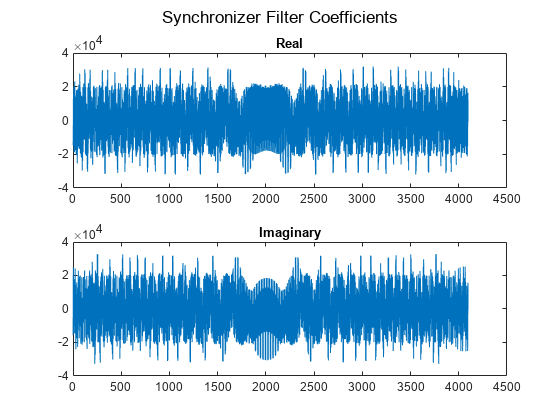

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Create Zadoff-Chu sequence
% Set ZC sequence to be 50% ZC and 50% ZP
sync_tx = log2(M)/sqrt(2)*exp(-1i*pi*ZC_root*(1:ZC_length).*((1:ZC_length)+1)/ZC_length); % ZC sequence
sync_tx_zp = [zeros(1,(nfft-ZC_length)/2),sync_tx,zeros(1,(nfft-ZC_length)/2)]; % Add ZP
sync_tx_time = ifft(ifftshift(sync_tx_zp),nfft); % ZC sequence in the time domain

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Create coe file for Xilinx FIR Compiler
sync_coef = conj(fliplr(sync_tx_time));
sync_coef_i = real(sync_coef); sync_coef_q = imag(sync_coef);
max_val_i = max(sync_coef_i);max_val_q = max(sync_coef_q);
if (max_val_i < max_val_q)
    max_val = max_val_q;
else
    max_val = max_val_i;
end
scaled_sync_coef_i = int16(sync_coef_i ./ max_val .* 32767);
scaled_sync_coef_q = int16(sync_coef_q ./ max_val .* 32767);
filename = "../Xilinx/Vivado/modules/data/zc_"+string(nfft)+"_nfft_"+ZC_length+"_ZC_13_root_i.coe";
file = fopen(filename,'w');
fprintf(file,"radix=10;\n");fprintf(file,"coefdata=\n");
fprintf(file,"%d,\n",scaled_sync_coef_i(1:end-1));
fprintf(file,"%d;",scaled_sync_coef_i(end));
fclose('all');
filename = "../Xilinx/Vivado/modules/data/zc_"+string(nfft)+"_nfft_"+ZC_length+"_ZC_13_root_q.coe";
file = fopen(filename,'w');
fprintf(file,"radix=10;\n");fprintf(file,"coefdata=\n");
fprintf(file,"%d,\n",scaled_sync_coef_q(1:end-1));
fprintf(file,"%d;",scaled_sync_coef_q(end));
fclose('all');

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Create txt file for SW
filename = "../Xilinx/SW_Source/ofdm/files/zc_seq_time_"+string(nfft)+"_nfft_"+ZC_length+"_ZC_13_root.txt";
file = fopen(filename,'w');
fprintf(file,"%d, %d\n",[int16(real(sync_tx_time)*tx_scale);int16(imag(sync_tx_time)*tx_scale)]);
fclose('all');

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Plot
figure(),subplot(2,1,1),plot(scaled_sync_coef_i),title('Real'),subplot(2,1,2),plot(scaled_sync_coef_q)
title('Imaginary'),sgtitle('Synchronizer Filter Coefficients')

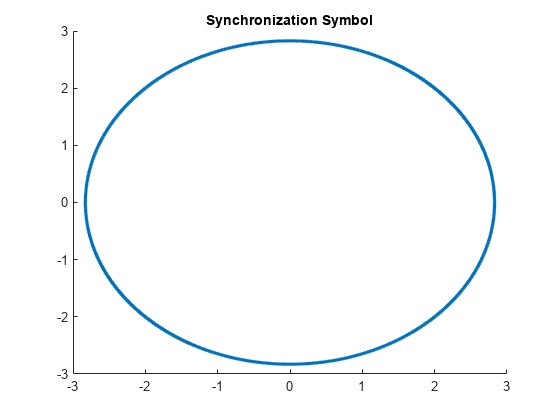

figure(),scatter(real(sync_tx),imag(sync_tx),'.'),title('Synchronization Symbol')

# **CARRIER ALLOCATION:**

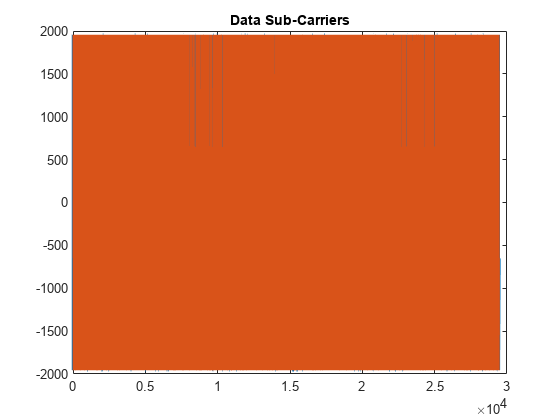

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% FFT carriers of data,pilot and ZP carriers
carriers = zeros(nfft,ofdm_symbols);
carriers(pilot_index,:) = reference_pilot;
carriers(data_index,:) = qpsk_mod_data;
carriers(zp_index,:) = zp_carrier;
carriers_zc = horzcat(sync_tx_zp.',carriers); % Allocate ZC symbol
carriers_zc = carriers_zc*tx_scale;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Read OFDM Parameters from TX Frequency file header
file = fopen('../Xilinx/SW_Source/ofdm/files/TxFreqData1.txt','r');
nfft_tmp = fscanf(file,"%d,",1);
ofdm_symbols_tmp = fscanf(file,"%d,",1);
cp_len_tmp = fscanf(file,"%d,",1);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Read Frequency domain carriers from SW file
freq_data_ofdm = [];
freq_data_ofdm = fscanf(file,"%f, %f", [2 nfft*ofdm_symbols]);
freq_data_ofdm = complex(freq_data_ofdm(1,:),freq_data_ofdm(2,:));
fclose('all');
freq_data_ofdm_1 = reshape(freq_data_ofdm,[nfft ofdm_symbols]);
freq_data_ofdm = [zeros(1,nfft),freq_data_ofdm];

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Plotting
p_plot = reshape(qpsk_mod_data*tx_scale,[1 ofdm_symbols*data_carriers]);
p_plot_sw = reshape(freq_data_ofdm_1(data_index,:),[1 ofdm_symbols*data_carriers]);
%p_plot_sw(1:data_carriers) = [];
figure(),plot(real(p_plot),'LineWidth',2),hold on,plot(real(p_plot_sw)),title('Data Sub-Carriers')

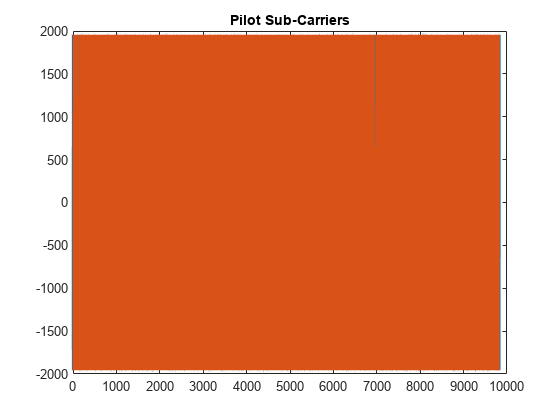

p_plot = reshape(reference_pilot*tx_scale,[1 ofdm_symbols*pilot_carriers]);
p_plot_sw = reshape(freq_data_ofdm_1(pilot_index,:),[1 ofdm_symbols*pilot_carriers]);
figure(),plot(real(p_plot),'LineWidth',2),hold on,plot(real(p_plot_sw)),title('Pilot Sub-Carriers')

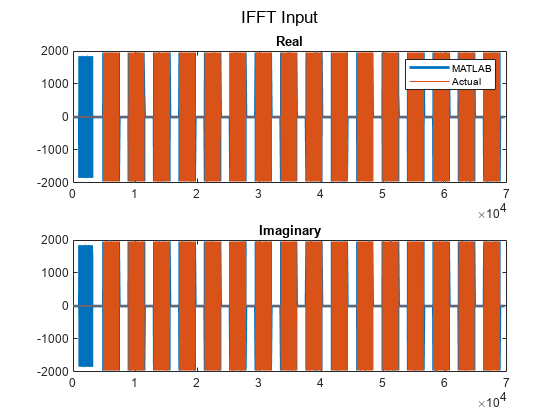

carriers_plot = reshape(carriers_zc,[1 (ofdm_symbols+1)*nfft]);
figure(),subplot(2,1,1),plot(real(carriers_plot),'LineWidth',2),hold on,plot(real(freq_data_ofdm)),legend('MATLAB','Actual'),title('Real')
subplot(2,1,2),plot(imag(carriers_plot),'LineWidth',2),hold on,plot(imag(freq_data_ofdm)),title('Imaginary'),sgtitle('IFFT Input')

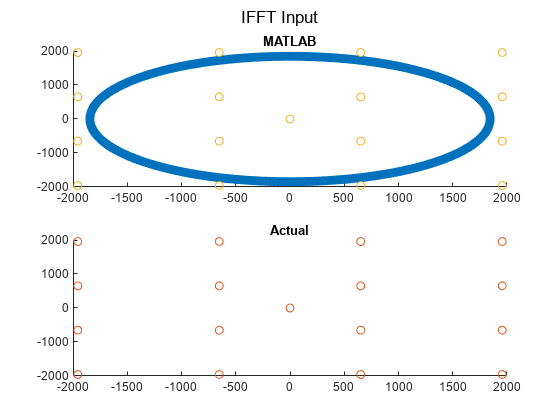

figure(),subplot(2,1,1),scatter(real(carriers_zc),imag(carriers_zc)),title('MATLAB')
subplot(2,1,2),scatter(real(freq_data_ofdm_1),imag(freq_data_ofdm_1)),title('Actual'),sgtitle('IFFT Input')

# **IFFT:**

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Ifftshift to reorder carriers in correct order for IFFT
cp_start = nfft-cp_len;
ifft_sub_carriers = zeros(nfft,ofdm_symbols+1);
for i=1:ofdm_symbols+1 % do in loop so that ifftshift works per symbol instead of per frame
    ifft_sub_carriers(:,i) = ifft(ifftshift(carriers_zc(:,i)),nfft);
end

# **CP INSERTION:**

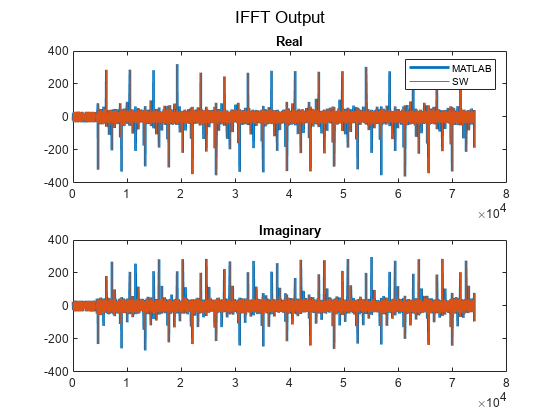

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Cyclic Prefix (copy end of symbol to beginning
cp_start = nfft-cp_len;
cp = ifft_sub_carriers(cp_start+1:end,:);
cp(:,1) = complex(0,0); % No CP for synchronization symbol, set as GP
ofdm_tx_signal_par = zeros(nfft+cp_len,ofdm_symbols+1);
for i=1:ofdm_symbols+1
    if (i == 1) % Synchronization symbol
        ofdm_tx_signal_par(:,1) = [ifft_sub_carriers(:,1);cp(:,1)];
    else
        ofdm_tx_signal_par(:,i) = [cp(:,i);ifft_sub_carriers(:,i)];
    end
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Read IFFT output from SW
file = fopen('../Xilinx/SW_Source/ofdm/files/TxIfftSamples1.txt','r');
nfft_tmp = fscanf(file,"%d,",1);
ofdm_symbols_tmp = fscanf(file,"%d,",1);
cp_len_tmp = fscanf(file,"%d,",1);
if (nfft_tmp~=nfft||ofdm_symbols_tmp~=ofdm_symbols||cp_len_tmp~=cp_len)
    disp('Error with header information')
end
ifft_sw = fscanf(file,"%d, %d",[2 (nfft+cp_len)*(ofdm_symbols+1)]);
ifft_sw = complex(ifft_sw(1,:),ifft_sw(2,:));
fclose('all');

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Plot MATLAB vs IFFT output from SW
ofdm_tx_signal_re = reshape(ofdm_tx_signal_par,[1 (ofdm_symbols+1)*(nfft+cp_len)]);
figure(),subplot(2,1,1),plot(real(ofdm_tx_signal_re),'LineWidth',2),hold on,plot(real(ifft_sw)),legend('MATLAB','SW'),title('Real')
subplot(2,1,2),plot(imag(ofdm_tx_signal_re),'LineWidth',2),hold on,plot(imag(ifft_sw)),title('Imaginary'),sgtitle('IFFT Output')

# **Parallel to Serial:**

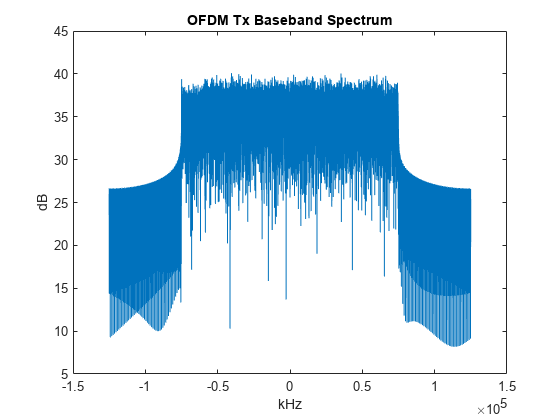

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Convert into vector of time domain samples
ofdm_tx_signal_ser = reshape(ofdm_tx_signal_par,[(nfft+cp_len)*(ofdm_symbols+1) 1]);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Plot MATLAB baseband spectrum
figure(),plot(F,10*log10(abs(fftshift(fft(ofdm_tx_signal_ser,nfft_p))))),title('OFDM Tx Baseband Spectrum'),xlabel('kHz'),ylabel('dB')

# **DUC:**

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Perform DUC with matlab function
[ofdm_duc_signal, coef] = interp(ofdm_tx_signal_ser,Interp_val,10,1);
ofdm_duc_signal = ofdm_duc_signal.';

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Read CIC output from DUC DDC loopback vivado sim
if (SW_DUC_DDC_LOOP)
    file = fopen('../Xilinx/Vivado/modules/sim/cic_loop.txt','r');
    cic_sw = fscanf(file,"%d, %d\n", [2 (ofdm_symbols+1)*(nfft+cp_len)*Interp_val]);
    fclose('all');
    cic_sw = complex(cic_sw(1,:),cic_sw(2,:));
    cic_sw = 1.5*circshift(cic_sw,-Interp_val); % Account for HW delay and scaling
    figure(),subplot(2,1,1),plot(real(ofdm_duc_signal),'LineWidth',2),hold on,
    plot(real(cic_sw)),legend('MATLAB','Vivado Sim'),title('Real'),subplot(2,1,2)
    plot(imag(ofdm_duc_signal),'LineWidth',2),hold on,plot(imag(cic_sw)),title('Imaginary')
    sgtitle('Interpolator CIC Filter Output')
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% If Enabled set rest of processing to CIC Interpolator output from DUC DDC
% Loopback vivado sim
if (SW_DUC)
    ofdm_duc_signal = cic_sw;
end

# **IQ Mixer TX:**

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Use oscillator at Fc for IQ mixer
ofdm_duc_signal_i = real(ofdm_duc_signal) .* cos(2*pi*Fc*t_up);
ofdm_duc_signal_q = imag(ofdm_duc_signal) .* -sin(2*pi*Fc*t_up);
ofdm_duc_signal_real = ofdm_duc_signal_i + ofdm_duc_signal_q;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Read IQ Mixer output after CIC from DUC DDC loopback vivado sim
if (SW_DUC_DDC_LOOP)
    file = fopen('../Xilinx/Vivado/modules/sim/duc_loop.txt','r');
    duc_sw_samp = fscanf(file,"%d\n",(ofdm_symbols+1)*(nfft+cp_len)*Interp_val);
    fclose('all');
    duc_sw_samp = 0.05*circshift(duc_sw_samp,-Interp_val-5); % Factor for HW scaling and delay
    figure(),plot(ofdm_duc_signal_real,'LineWidth',2),hold on,plot(duc_sw_samp)
    legend('MATLAB','Vivado Sim'),title('Tx Signal')
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% If enabled Set rest of processing using DUC IQ Mixer output samples from DUC DDC loopback vivado sim
if (SW_TX)
    ofdm_duc_signal_real = duc_sw_samp.';
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% If enabled create samples for ADC vivado sim
if (SIM_DDC_40M)
    file = fopen('../Xilinx/Vivado/modules/sim/ddc_40M_input.txt','w');
    fprintf(file,"%d\n", int16(channel_scale*ofdm_duc_signal_real));
    fclose('all');
end

# **Channel:**

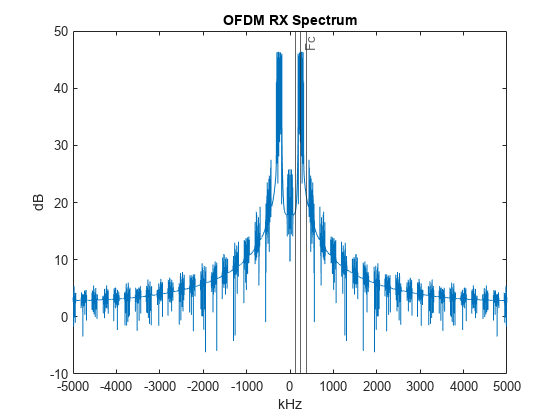

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% AWGN + Multipath channel
if (SIM_DDC_40M)
    ofdm_duc_signal_real = channel_scale*ofdm_duc_signal_real;
end
SNR = 250;
ofdm_tx_signal_ch = awgn(ofdm_duc_signal_real,SNR);
multipath = [0 0.1 0.05 0 0.9 0 0 0.9 0.3 0.5 0.6 0.8 0 0 0.7];
if (ENABLE_MULTIPATH_CH)
    ofdm_tx_signal_ch = filter(multipath,1,ofdm_tx_signal_ch);
end
ofdm_tx_signal_ch = [ofdm_tx_signal_ch(end-Delay_interp+1:end),ofdm_tx_signal_ch ofdm_tx_signal_ch(end-2*Delay_interp+1:end-Delay_interp)];

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Plot RX Spectrum
figure(),plot(F_up/1000,10*log10(abs(fftshift(fft(ofdm_tx_signal_ch,nfft_p))))),title('OFDM RX Spectrum'),xline([(Fc-BW/2)/1000 Fc/1000 (Fc+BW/2)/1000],'-',{' ','Fc',' '})
xlabel('kHz'),ylabel('dB')

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Write real DAC samples to file for tb
% file = fopen('../Xilinx/Vivado/modules/sim/iq_mix_test_in.txt','wt');
% fprintf(file,"%d\n",int16(ofdm_duc_signal_real),length(ofdm_duc_signal_real));
% fclose('all');

# **IQ Mixer RX:**

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
i_ddc = ofdm_tx_signal_ch .* cos(2*pi*Fc*t_up_rx);
q_ddc = ofdm_tx_signal_ch .* -sin(2*pi*Fc*t_up_rx);
ddc_signal = complex(i_ddc,q_ddc);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Read samples from ADC_Chain Vivado sim
if (SIM_DDC_40M)
    file = fopen('../Xilinx/Vivado/modules/sim/iq_mix_out.txt','r');
    iq_mix_sim = fscanf(file,"%d, %d\n", [2 (ofdm_symbols+1)*(nfft+cp_len)*Interp_val]);
    iq_mix_sim1 = complex(iq_mix_sim(1,:),iq_mix_sim(2,:));
    iq_mix_sim = 5*iq_mix_sim1;
    fclose('all');
    figure(),subplot(2,1,1),plot(real(ddc_signal),'LineWidth',2),hold on,plot(real(iq_mix_sim))
    title('Real'),subplot(2,1,2),plot(imag(ddc_signal),'LineWidth',2),hold on,plot(imag(iq_mix_sim))
    title('Imaginary'),title('IQ Mixer Output')
end
if (SIM_RX_MIX)
    ddc_signal = iq_mix_sim;
end

# **DDC:**

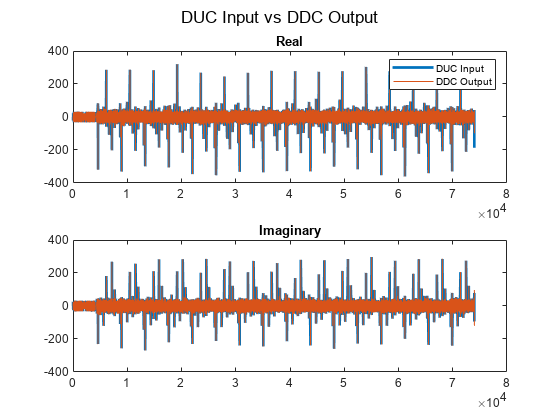

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Matlab decimate function - Ideal
ddc_base_signal_real = decimate(real(ddc_signal),Interp_val,4096,'Fir'); % Normal DDC
ddc_base_signal_imag = decimate(imag(ddc_signal),Interp_val,4096,'FIR');
ddc_base_signal = complex(ddc_base_signal_real,ddc_base_signal_imag);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Compare Matlab DDC output to DUC input
ddc_scale = 2;
figure(),subplot(2,1,1),plot(real(ofdm_tx_signal_ser),'LineWidth',2),hold on,plot(ddc_scale*real(ddc_base_signal)),title('Real')
legend('DUC Input','DDC Output'),subplot(2,1,2),plot(imag(ofdm_tx_signal_ser),'LineWidth',2),hold on,plot(ddc_scale*imag(ddc_base_signal)),title('Imaginary')
sgtitle('DUC Input vs DDC Output')

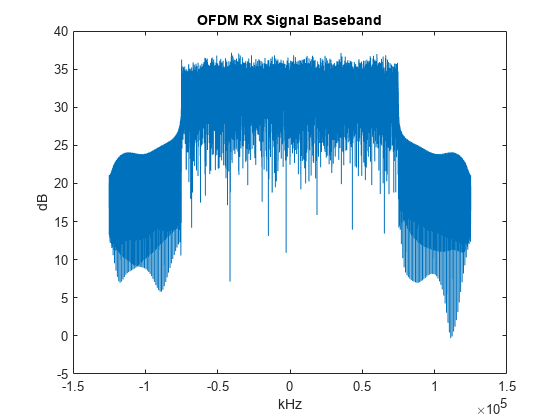


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Read samples from ADC Vivado sim
if (SIM_DDC_40M)
    file = fopen('../Xilinx/Vivado/modules/sim/iq_mix_test_out.txt','r');
    ddc_sim = fscanf(file,"%d, %d\n", [2 (ofdm_symbols+1)*(nfft+cp_len)]);
    ddc_sim = complex(ddc_sim(1,:),ddc_sim(2,:));
    ddc_sim = 0.033*ddc_sim;
    if (~SIM_RX_MIX)
        %ddc_base_signal = ddc_sim;
    end
    fclose('all');
    figure(),subplot(2,1,1),plot(ddc_base_signal_real,'LineWidth',2),hold on,plot(real(ddc_sim)),title('Real')
    legend('MATLAB','Vivado'),subplot(2,1,2),plot(ddc_base_signal_imag,'LineWidth',2),hold on,plot(imag(ddc_sim)),title('Imaginary')
    sgtitle('DDC Output, MATLAB vs Vivado')
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Plot
figure(),plot(F,10*log10(abs(fftshift(fft(ddc_base_signal,nfft_p))))),title('OFDM RX Signal Baseband'),xlabel('kHz'),ylabel('dB')

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Skip DUC/DDC for Ideal RX signal
if (IFFT_FFT_LOOPBACK)
    ddc_base_signal = ofdm_tx_signal_ser;
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
if (SIM_SYNC_SAMPLES)
    file = fopen('../Xilinx/Vivado/modules/sim/ddc_ch_signal.txt','w');
    tmp_ddc = int16(ddc_base_signal).';
    fprintf(file,"%d, %d\n",[real(tmp_ddc);imag(tmp_ddc)]);
    fclose('all');
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% SW DUC => DDC loopback (with IQ mixer)
if (SW_DUC_DDC_LOOP)
    file = fopen('../Xilinx/Vivado/modules/sim/duc_ddc_loop.txt','r');
    duc_ddc_loop_sw = fscanf(file,"%d, %d\n",[2 (ofdm_symbols+1)*(nfft+cp_len)]);
    duc_ddc_loop_sw = complex(duc_ddc_loop_sw(1,:),duc_ddc_loop_sw(2,:));
    duc_ddc_loop_sw = 0.02*[duc_ddc_loop_sw(3:end), 0, 0];
    figure(),subplot(2,1,1),plot(real(ddc_base_signal),'LineWidth',2),hold on
    plot(real(duc_ddc_loop_sw)),legend('MATLAB','Vivado'),title('Real'),subplot(2,1,2),plot(imag(ddc_base_signal), ...
        'LineWidth',2),hold on,plot(imag(duc_ddc_loop_sw)),title('Imaginary'),sgtitle('DDC Output')
    fclose('all');
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% SW DUC => DDC loopback (with IQ mixer)
if (SW_DDC_NO_MIX)
    file = fopen('../Xilinx/Vivado/modules/sim/duc_ddc_no_mix_loop.txt','r');
    duc_ddc_no_mix = fscanf(file,"%d, %d\n",[2 (ofdm_symbols+1)*(nfft+cp_len)]);
    duc_ddc_no_mix = complex(duc_ddc_no_mix(1,:),duc_ddc_no_mix(2,:));
    duc_ddc_no_mix = [duc_ddc_no_mix(3:end),0,0];
    figure(),subplot(2,1,1),plot(real(ddc_base_signal),'LineWidth',2),hold on,plot(real(duc_ddc_no_mix))
    title('Real'),legend('MATLAB','Vivado'),subplot(2,1,2),plot(imag(ddc_base_signal),'LineWidth',2),
    hold on,plot(imag(duc_ddc_no_mix)),title('Imaginary'),sgtitle('DUC Output')
    fclose('all');
end
if (SW_DDC)
    ddc_base_signal = duc_ddc_loop_sw;
end

# **SYNCHRONIZATION:**

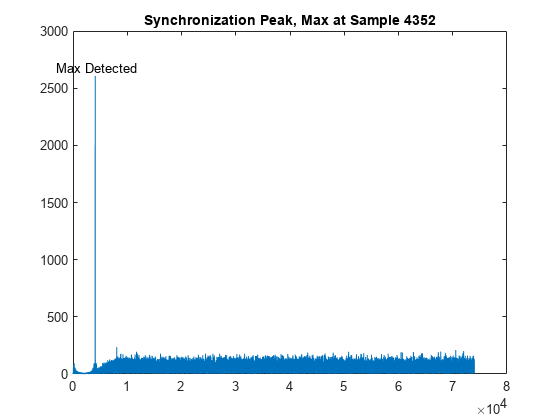

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Synchronization is detected in time domain
% Perform synchronization with filter insead of xcorr
% Define the matched filter as the time-reversed complex conjugate 
% of the ZC sequence.
%sync_tx_time = ifft_signal(:,1);
sync_coef = conj(fliplr(sync_tx_time)); % Matched filter
sync_corr_filt = abs(filter(sync_coef,1,ddc_base_signal)); 
[val,ind] = max(sync_corr_filt);
ind = ind+cp_len-sync_samples_early; % Remove GP from index

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Delete the Synchronization symbol and everything before it as well as
% everything after the last symbol
ofdm_rx_sync_signal = ddc_base_signal;
ofdm_rx_sync_signal([1:ind,ind+1+(nfft+cp_len)*ofdm_symbols:end]) = []; % Delete
% Check if signal is long enough
if (length(ofdm_rx_sync_signal) ~= (nfft+cp_len)*ofdm_symbols)
    tmp = zeros(1,(nfft+cp_len)*ofdm_symbols-length(ofdm_rx_sync_signal));
    ofdm_rx_sync_signal = [ofdm_rx_sync_signal tmp];
    warning('Deleted too much of signal')
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Write synchronized samples to file 
file = fopen('../Xilinx/SW_Source/ofdm/files/RxFftInjectData1.txt','w');
fprintf(file,"%d,\n",nfft);
fprintf(file,"%d,\n",cp_len);
fprintf(file,"%d,\n",ofdm_symbols);
sync_sw = [real(ofdm_rx_sync_signal);imag(ofdm_rx_sync_signal)];
fprintf(file,"%d, %d\n", [int16(sync_sw)]);
fclose('all');

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Plot
figure(),plot(sync_corr_filt),hold on,text(ind,val,'Max Detected','HorizontalAlignment','center','VerticalAlignment','bottom')
title(['Synchronization Peak, Max at Sample ',num2str(ind)])

# **Serial to Parallel:**


ofdm_rx_signal_par = reshape(ofdm_rx_sync_signal,[nfft+cp_len ofdm_symbols]);
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% % Write simulated channel signal to file
% file = fopen('../Xilinx/SW_Source/ofdm/files/RxFftInjectData1.txt','wt');
% fprintf(file,"%d,\n",nfft);
% fprintf(file,"%d,\n",cp_len);
% fprintf(file,"%d,\n",ofdm_symbols);
% for i = 1:ofdm_symbols*(nfft+cp_len)
%     fprintf(file,"%0.6f, %0.6f\n",real(ofdm_rx_signal_ch(i)),imag(ofdm_rx_signal_ch(i)));
% end
fclose('all');

# **CP Removal and CFO correction:**

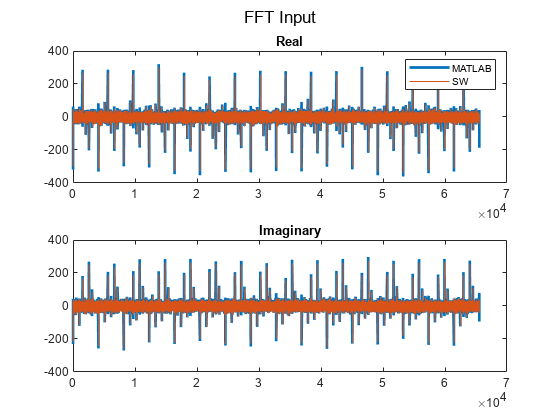

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Save and remove CP
cp_rm_signal = ofdm_rx_signal_par;
cp_rm_signal(1:cp_len,:) = []; % Remove CP
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% CFO correction
ofdm_cfo_sig = [];
cfo_est = 0;
for i = 1:ofdm_symbols
    cp_cfo_begin = ofdm_rx_signal_par(1:cp_len,i); % Obtain CP at beginning of symbol
    cp_cfo_end = ofdm_rx_signal_par(nfft+1:end,i); % Obtain copy at end of symbol
    tmp = cp_cfo_end.*conj(cp_cfo_begin);          % Correlate
    sum_val = sum(tmp);
    tan_val = atan2(imag(sum_val),real(sum_val));
    normalized_cfo_est = 1*tan_val;
    cfo_est = normalized_cfo_est*scs;
    ofdm_cfo_sig(:,i) = cp_rm_signal(:,i).*(cos(cfo_est*t(1:nfft))+1i*sin(cfo_est*t(1:nfft)))';
end
%cp_rm_signal = ofdm_cfo_sig;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% FFT input 
file = fopen('../Xilinx/SW_Source/ofdm/files/RxFftSamples1.txt','r');
fft_sw = fscanf(file,"%d, %d\n", [2 ofdm_symbols*nfft]);
fclose('all');

fft_sw = complex(fft_sw(1,:),fft_sw(2,:));
fft_sw = 2.3*fft_sw;
if (IFFT_FFT_LOOPBACK)
    cp_rm_signal_plot = reshape(cp_rm_signal,[1 ofdm_symbols*nfft]);
else
    cp_rm_signal_plot = 2*reshape(cp_rm_signal,[1 ofdm_symbols*nfft]);
end
figure(),subplot(2,1,1),plot(real(cp_rm_signal_plot),'LineWidth',2),hold on,plot(real(fft_sw)),title('Real'),legend('MATLAB','SW')
subplot(2,1,2),plot(imag(cp_rm_signal_plot),'LineWidth',2),hold on,plot(imag(fft_sw)),title('Imaginary'),sgtitle('FFT Input')

# **FFT Output:**

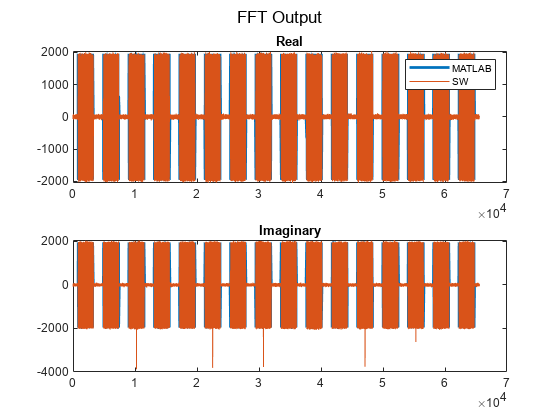

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% FFTshift same as TX (fftshift = Ifftshift)
fft_signal = zeros(nfft,ofdm_symbols);
for i=1:ofdm_symbols % Do fftshift per symbol
    fft_signal(:,i) = fftshift(fft(cp_rm_signal(:,i),nfft));
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Obtain FFT output from SW
file = fopen('../Xilinx/SW_Source/ofdm/files/RxFreqData1.txt','r');
nfft_tmp = fscanf(file,"%d,",1);
ofdm_symbols_tmp = fscanf(file,"%d,",1);
cp_len_tmp = fscanf(file,"%d,",1);
if (nfft_tmp~=nfft||ofdm_symbols_tmp~=ofdm_symbols||cp_len_tmp~=cp_len)
    disp('Error with header information');
end
Fft_data_sw = fscanf(file,"%f, %f", [2 nfft*ofdm_symbols]);
Fft_data_sw = complex(Fft_data_sw(1,:),Fft_data_sw(2,:));
fclose('all');

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Plot
if (IFFT_FFT_LOOPBACK)
    fft_signal_re = reshape(fft_signal,[1 ofdm_symbols*nfft]);
else
    fft_signal_re = 1.9*reshape(fft_signal,[1 ofdm_symbols*nfft]);
end
figure(),subplot(2,1,1),plot(real(fft_signal_re),'LineWidth',2),hold on,plot(real(Fft_data_sw)),legend('MATLAB','SW'),title('Real')
subplot(2,1,2),plot(imag(fft_signal_re),'LineWidth',2),hold on,plot(imag(Fft_data_sw)),title('Imaginary'),sgtitle('FFT Output')

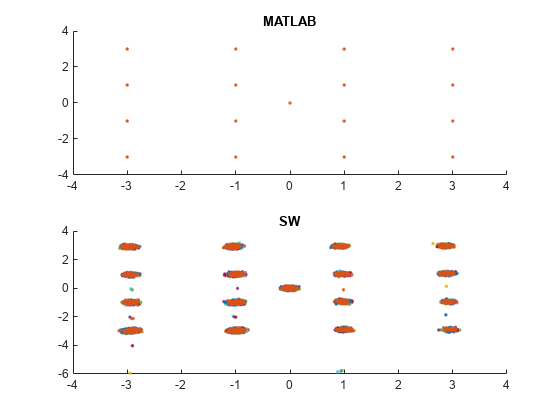

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Plot (with pilot carriers)
Fft_data_sw = reshape(Fft_data_sw,[nfft, ofdm_symbols]);
lim = sqrt(M)+1;
%y_lim = [-lim lim]; x_lim = [-lim lim];
figure(),subplot(2,1,1),scatter(real(fft_signal/tx_scale),imag(fft_signal/tx_scale),'.'),title('MATLAB')%,ylim(y_lim),xlim(x_lim)
subplot(2,1,2),scatter(real(Fft_data_sw/tx_scale),imag(Fft_data_sw/tx_scale),'.'),title('SW')%,ylim(y_lim),xlim(x_lim)

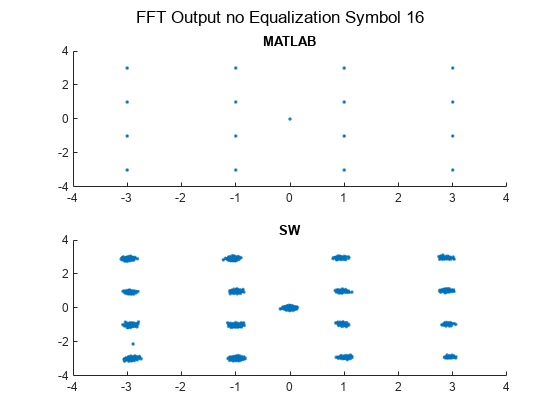

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Plot playback of packet per symbol
figure()
for i = 1:ofdm_symbols
    subplot(2,1,1),scatter(real(fft_signal(:,i)/tx_scale),imag(fft_signal(:,i)/tx_scale),'.')
    title('MATLAB')
    subplot(2,1,2),scatter(real(Fft_data_sw(:,i)/tx_scale),imag(Fft_data_sw(:,i)/tx_scale),'.')
    title('SW')
    sgtitle(['FFT Output no Equalization Symbol ',num2str(i)])
    pause(0.1);
end

# **Equalization:**

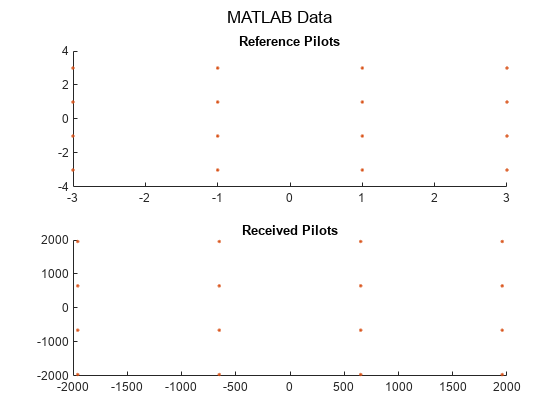

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Get RX pilots
fft_signal_eq = fft_signal;
P_RX = fft_signal_eq(pilot_index,:); % Get Rx Pilots

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Plot RX Pilots
figure(),subplot(2,1,1),scatter(real(reference_pilot),imag(reference_pilot),'.'),title('Reference Pilots')
subplot(2,1,2),scatter(real(P_RX),imag(P_RX),'.'),title('Received Pilots'),sgtitle('MATLAB Data')

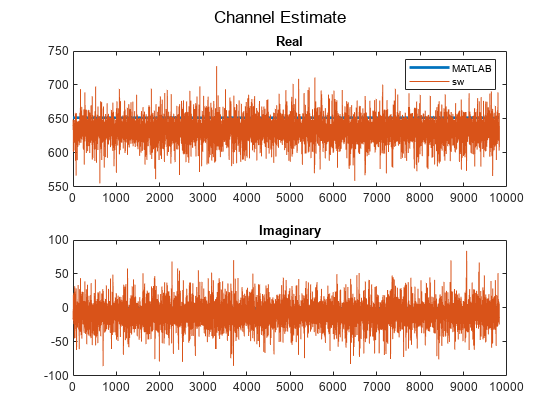

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Get Channel Estimate
%P_RX = P_RX / tx_scale;
%reference_pilot = reference_pilot*tx_scale;
P_RX_re = real(P_RX); P_RX_im = imag(P_RX); P_re = real(reference_pilot); P_im = imag(reference_pilot);
P_RX_im = -P_RX_im; P_im = -P_im;
H = (P_RX_re.*P_re + P_RX_im.*P_im)./(P_re.^2 + P_im.^2) + 1i*(P_RX_im.*P_re - P_RX_re.*P_im)./(P_re.^2 + P_im.^2);
H_interp = interp1(pilot_index,H,1:nfft,'previous');
[a,b] = size(H_interp);
if (a==1)
    H_interp = H_interp.';
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Check if pilots wrap data
% Check if pilots wrap data
if (last_pilot_carrier ~= pilot_index(end))
    if (last_pilot_carrier-1 ~= pilot_index(end))
        if (last_pilot_carrier-2 ~= pilot_index(end))
            disp('Pilots do no wrap, setting last pilot to previous pilot')
            H_interp(data_index(end-2),:) = H_interp(data_index(end-3),:);
        end
        disp('Pilots do no wrap, setting last pilot to previous pilot')
        H_interp(data_index(end-1),:) = H_interp(data_index(end-2),:);
    end    
    disp('Pilots do no wrap, setting last pilot to previous pilot')
    H_interp(data_index(end),:) = H_interp(data_index(end-1),:);
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Equalize data with channel estimates
H_ZF_re = real(H_interp); H_ZF_im = imag(H_interp);fft_re = real(fft_signal_eq);fft_im = imag(fft_signal_eq);
H_ZF_im = -H_ZF_im;
% Equalize
Z_EQ_ZF = (fft_re.*H_ZF_re + fft_im.*H_ZF_im)./(H_ZF_re.^2 + H_ZF_im.^2) + 1i*(fft_im.*H_ZF_re - fft_re.*H_ZF_im)./(H_ZF_re.^2 + H_ZF_im.^2);
fft_signal_eq([pilot_index,zp_index],:) = [];
Z_EQ_ZF([pilot_index,zp_index],:) = [];

% Remove pilots
Fft_data_sw_eq = Fft_data_sw;
Fft_data_sw_eq([pilot_index,zp_index],:) = [];

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Read CH Est from SW
file = fopen('../Xilinx/SW_Source/ofdm/files/ChannelEstimate1.txt','r');
H_sw = [];
for i = 1:pilot_carriers*ofdm_symbols
    tmp_i = fscanf(file,"%lf");
    tmp_q = fscanf(file,",%lf");
    tmp_iq = complex(tmp_i,tmp_q);
    H_sw = [H_sw tmp_iq];
end
H_plot = reshape(H,[1 ofdm_symbols*pilot_carriers]);
figure(),subplot(2,1,1),plot(real(H_plot),'LineWidth',2),hold on,plot(real(H_sw)),legend('MATLAB','sw'),title('Real')
subplot(2,1,2),plot(imag(H_plot),'LineWidth',2),hold on,plot(imag(H_sw)),title('Imaginary'),sgtitle('Channel Estimate')

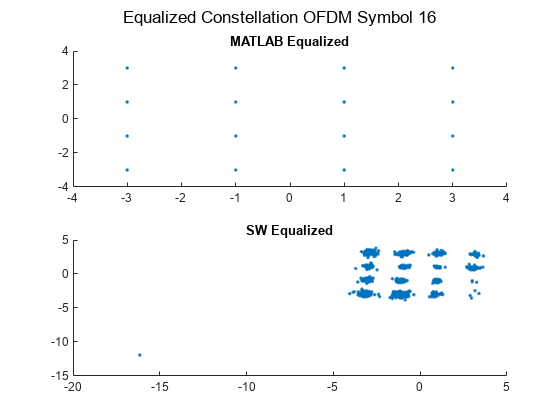

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Read Equalized data from SW
file = fopen('../Xilinx/SW_Source/ofdm/files/RxFreqDataEQ1.txt','r');
nfft_tmp = fscanf(file,"%d,\n",1);
M_tmp = fscanf(file,"%d,\n",1);
ofdm_symbols_tmp = fscanf(file,"%d,\n",1);
if (nfft_tmp~=nfft||M_tmp~=M||ofdm_symbols_tmp~=ofdm_symbols)
    disp('Error with Header information')
end
EQ_sw = fscanf(file,"%f, %f", [2 nfft*ofdm_symbols]);
EQ_sw = complex(EQ_sw(1,:),EQ_sw(2,:));
Z_EQ_ZF_plot = reshape(Z_EQ_ZF,[1 ofdm_symbols*data_carriers]);
EQ_sw = reshape(EQ_sw,[nfft ofdm_symbols]);
EQ_sw([zp_index,pilot_index],:) = []; % Remove ZP and Pilot carriers
EQ_sw_plot = reshape(EQ_sw,[1 ofdm_symbols*data_carriers]);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Plot playback of frame per symbol
figure()
for i = 1:ofdm_symbols
    %subplot(3,1,1),scatter(real(fft_signal_eq),imag(fft_signal_eq),'.'),title('MATLAB no Equalization')
    subplot(2,1,1),scatter(real(Z_EQ_ZF(:,i)),imag(Z_EQ_ZF(:,i)),'.'),title('MATLAB Equalized')
    subplot(2,1,2),scatter(real(EQ_sw(:,i)),imag(EQ_sw(:,i)),'.'),title('SW Equalized')
    sgtitle(['Equalized Constellation OFDM Symbol ',num2str(i)])
    pause(0.1)
end

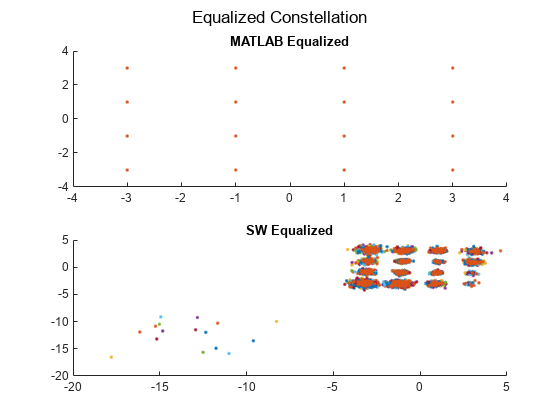

figure()
subplot(2,1,1),scatter(real(Z_EQ_ZF),imag(Z_EQ_ZF),'.'),title('MATLAB Equalized')
subplot(2,1,2),scatter(real(EQ_sw),imag(EQ_sw),'.'),title('SW Equalized')
sgtitle('Equalized Constellation')

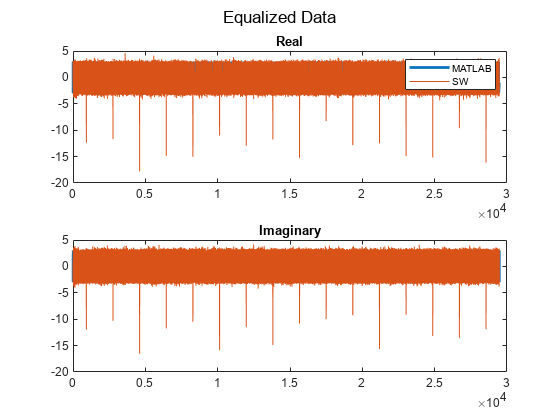

figure(),subplot(2,1,1),plot(real(Z_EQ_ZF_plot),'LineWidth',2),hold on,plot(real(EQ_sw_plot)),legend('MATLAB','SW'),title('Real')
subplot(2,1,2),plot(imag(Z_EQ_ZF_plot),'LineWidth',2),hold on,plot(imag(EQ_sw_plot)),title('Imaginary'),sgtitle('Equalized Data')

# **QAM Demodulation:**

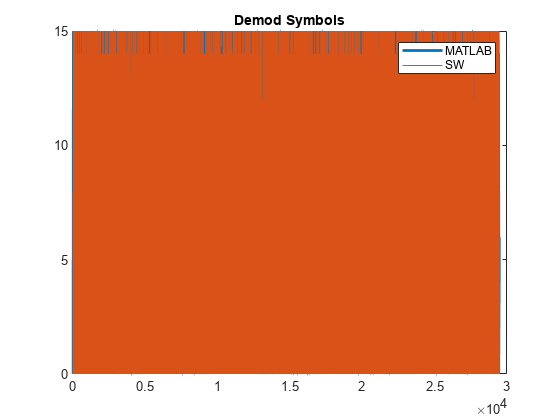

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Demod
demod_data = qamdemod(Z_EQ_ZF,M);
demod_sw = qamdemod(EQ_sw,M);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Plot 
demod_data_plot = reshape(demod_data,[1 ofdm_symbols*data_carriers]);
demod_sw_plot = reshape(demod_sw,[1 ofdm_symbols*data_carriers]);
figure(),plot(demod_data_plot,'LineWidth',2),hold on,plot(demod_sw_plot),legend('MATLAB','SW'),title('Demod Symbols')

# **Error Rate:**

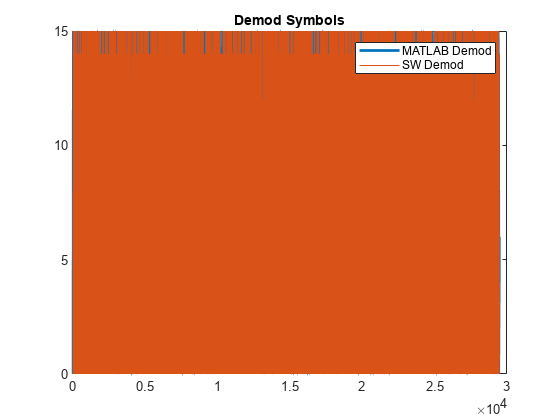

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Read demodulated Symbol Data
file = fopen('../Xilinx/SW_Source/ofdm/files/RxDemodData1.txt','r');
nfft_tmp = fscanf(file,"%d",1);
M_tmp = fscanf(file,"%d",1);
ofdm_symbols_tmp = fscanf(file,"%d",1);
if (nfft_tmp~=nfft||M_tmp~=M||ofdm_symbols_tmp~=ofdm_symbols)
    disp('Error with header information');
end
data_char_rx = fscanf(file,"%d",(data_carriers)*ofdm_symbols);
fclose('all');

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Plot
figure(),plot(demod_sw_plot,'LineWidth',2),hold on,plot(data_char_rx),legend('MATLAB Demod','SW Demod'),title('Demod Symbols')

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Calculate symbol error rate
ser_sw = symerr(data_char, data_char_rx)/numel(data_char);
ser_mat = symerr(data, demod_data)/numel(data);

# **Analysis:**

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Get EVM measurements
evm = comm.EVM(AveragingDimensions=[1 2],MaximumEVMOutputPort=1);
[mat_evm mat_evm_pk] = evm(qpsk_mod_data,Z_EQ_ZF);
[sw_evm sw_evm_pk] = evm(qpsk_mod_data,EQ_sw);

Equalization = ["MATLAB";"SW"];
SER = [ser_mat;ser_sw];
AverageEVM = [mat_evm;sw_evm];
PeakEVM = [mat_evm_pk;sw_evm_pk];
figure(),table(Equalization,SER,AverageEVM,PeakEVM)

ans = 2×4 table
    Equalization       SER        AverageEVM     PeakEVM  
    ____________    __________    __________    __________

      "MATLAB"               0    4.4357e-14    2.2216e-13
      "SW"          0.00040717        15.813        640.97


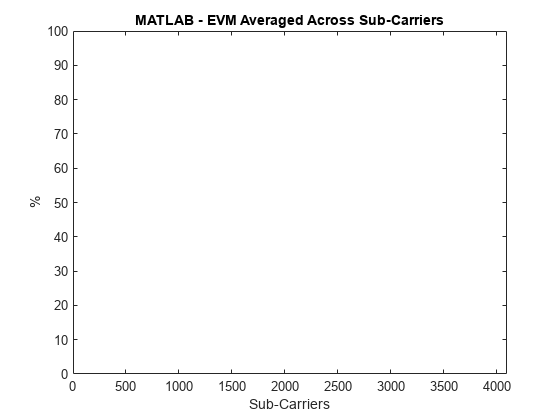

evm = comm.EVM(AveragingDimensions=2);
sw_evm = evm(qpsk_mod_data,Z_EQ_ZF);
y_lim = [0 100];
y1 = 1:nfft;
sw_evm_y = zeros(1,nfft);
sw_evm_y(data_index) = sw_evm;
figure(),bar(y1,sw_evm_y),title('MATLAB - EVM Averaged Across Sub-Carriers'),ax = gca; ax.YLim = y_lim;xlabel('Sub-Carriers'),ylabel('%')

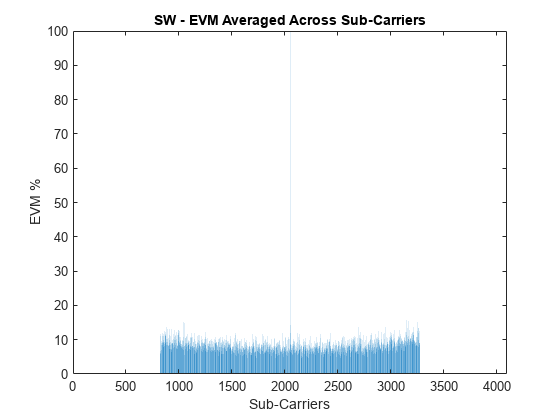


evm = comm.EVM(AveragingDimensions=2);
sw_evm = evm(qpsk_mod_data,EQ_sw);
y_lim = [0 100];
sw_evm_y = zeros(1,nfft);
sw_evm_y(data_index) = sw_evm;
figure(),bar(y1,sw_evm_y),title('SW - EVM Averaged Across Sub-Carriers'),ax = gca; ax.YLim = y_lim;
xlabel('Sub-Carriers'),ylabel('EVM %')

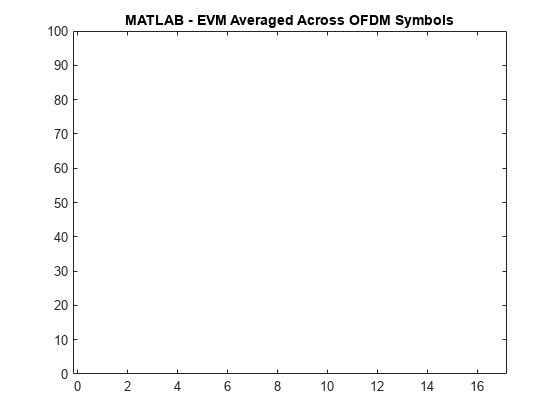

evm = comm.EVM(AveragingDimensions=1);
sw_evm = evm(qpsk_mod_data,Z_EQ_ZF);
y = 1:ofdm_symbols;
figure(),bar(y,sw_evm),title('MATLAB - EVM Averaged Across OFDM Symbols'),ax = gca; ax.YLim = y_lim;

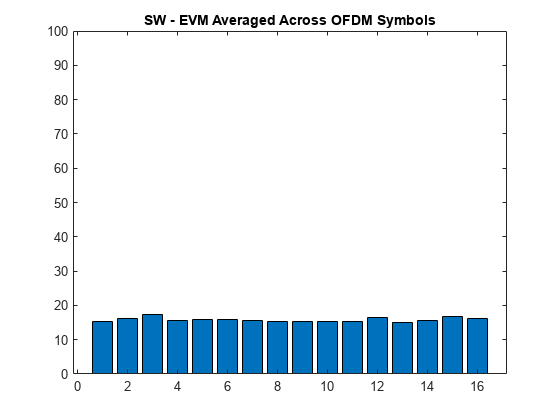

evm = comm.EVM(AveragingDimensions=1);
sw_evm = evm(qpsk_mod_data,EQ_sw);
y = 1:ofdm_symbols;
figure(),bar(y,sw_evm),title('SW - EVM Averaged Across OFDM Symbols'),ax = gca; ax.YLim = y_lim;

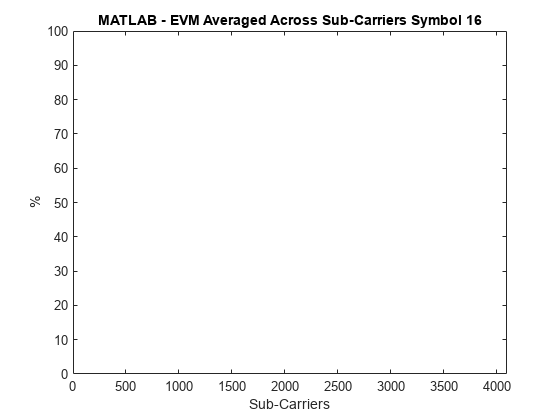

evm = comm.EVM(AveragingDimensions=2);
sw_evm = evm(qpsk_mod_data(:,ofdm_symbols),Z_EQ_ZF(:,ofdm_symbols));
y_lim = [0 100];
y1 = 1:nfft;
sw_evm_y = zeros(1,nfft);
sw_evm_y(data_index) = sw_evm;
figure(),bar(y1,sw_evm_y),title(['MATLAB - EVM Averaged Across Sub-Carriers Symbol ',num2str(ofdm_symbols)])
ax = gca; ax.YLim = y_lim;xlabel('Sub-Carriers'),ylabel('%')

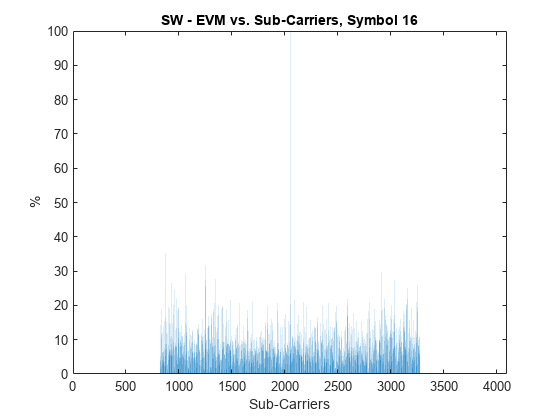

figure()
for i=1:ofdm_symbols
    sw_evm = evm(qpsk_mod_data(:,i),EQ_sw(:,i));
    sw_evm_y = zeros(1,nfft);
    sw_evm_y(data_index) = sw_evm;
    bar(y1,sw_evm_y),title(['SW - EVM vs. Sub-Carriers, Symbol ',num2str(i)])
    ax = gca; ax.YLim = y_lim; xlabel('Sub-Carriers'),ylabel('%')
    pause(0.01)
end